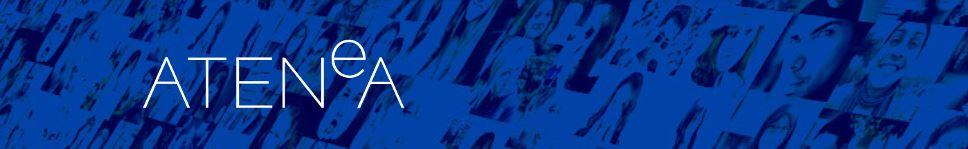

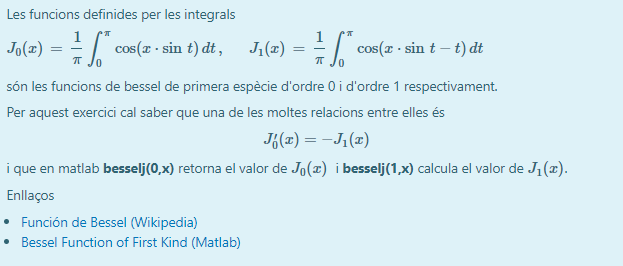

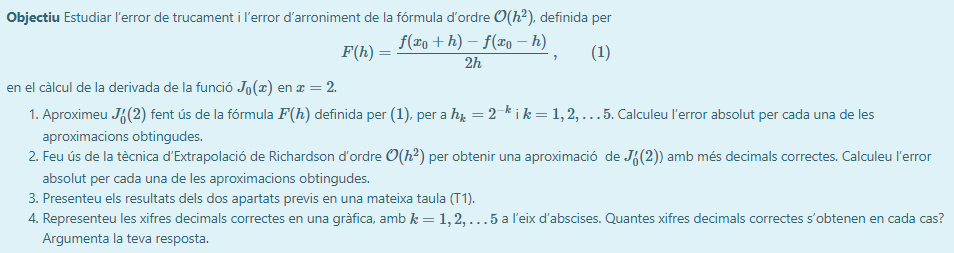

## Pràctica 1

`(1)`

f = @(x)besselj(0,x);
x = 2; n = 5;
valor = -besselj(1,x);
hk = 1:n;
h(1:n) = 1./2.^hk;
for k = 1:n
    ff(k) = (f(x+h(k))-f(x-h(k)))/(2*h(k));
end
er1 = abs(ff-valor);
V1 = [h(1:n); ff; er1]';
T = array2table(V1,'VariableNames',{'1/2^k','N_1 = Jo´(2)','error'}); disp(T)

     1/2^k     N_1 = Jo´(2)      error   
    _______    ____________    __________

        0.5      -0.56021        0.016513
       0.25      -0.57257       0.0041594
      0.125      -0.57568       0.0010418
     0.0625      -0.57646      0.00026058
    0.03125      -0.57666      6.5152e-05



`(2)`

% Primera extrapolació
R1(1) = 0; R1(2:n) = (4*ff(2:n)-ff(1:n-1))/(4^1-1);
er2 = abs(R1-valor); er2(1) = 0;
V2 = [h(1:n); R1; er2]';
T = array2table(V2,'VariableNames',{'1/2^k','N_2 = Jo´(2)','error'}); disp(T);

     1/2^k     N_2 = Jo´(2)      error   
    _______    ____________    __________

        0.5             0               0
       0.25      -0.57668       4.148e-05
      0.125      -0.57672      2.6049e-06
     0.0625      -0.57672        1.63e-07
    0.03125      -0.57672      1.0191e-08



% Segona extrapolació
R2(1:2) = 0; R2(3:n) = (4^2*R1(3:n)-R1(2:n-1))/(4^2-1);
er3 = abs(R2-valor); er3(1:2) = 0;
V3 = [h(1:n); R2; er3]';
T = array2table(V3,'VariableNames',{'1/2^k','N_3 = Jo´(2)','error'}); disp(T);

     1/2^k     N_3 = Jo´(2)      error   
    _______    ____________    __________

        0.5             0               0
       0.25             0               0
      0.125      -0.57672      1.3212e-08
     0.0625      -0.57672      2.0707e-10
    0.03125      -0.57672      3.2387e-12



% Tercera extrapolació
R3(1:3) = 0; R3(4:n) = (4^3*R2(4:n)-R2(3:n-1))/(4^3-1);
er4 = abs(R3-valor); er4(1:3) = 0;
V4 = [h(1:n); R3; er4]';
T = array2table(V4,'VariableNames',{'1/2^k','N_4 = Jo´(2)','error'}); disp(T);

     1/2^k     N_4 = Jo´(2)      error   
    _______    ____________    __________

        0.5             0               0
       0.25             0               0
      0.125             0               0
     0.0625      -0.57672      6.3682e-13
    0.03125      -0.57672      3.4417e-15



`(3)`

% Resultats previs en una mateix taula
V = [h(1:n); ff; R1; R2; R3; er4]';
T = array2table(V,'VariableNames',{'1/2^k','N_1 = Jo´(1)','N_2 = Jo´(2)','N_3 = Jo´(2)','N_4 = Jo´(2)','error'}); disp(T);

     1/2^k     N_1 = Jo´(1)    N_2 = Jo´(2)    N_3 = Jo´(2)    N_4 = Jo´(2)      error   
    _______    ____________    ____________    ____________    ____________    __________

        0.5      -0.56021               0               0               0               0
       0.25      -0.57257        -0.57668               0               0               0
      0.125      -0.57568        -0.57672        -0.57672               0               0
     0.0625      -0.57646        -0.57672        -0.57672        -0.57672      6.3682e-13
    0.03125      -0.57666        -0.57672        -0.57672        -0.57672      3.4417e-15



`(4)`

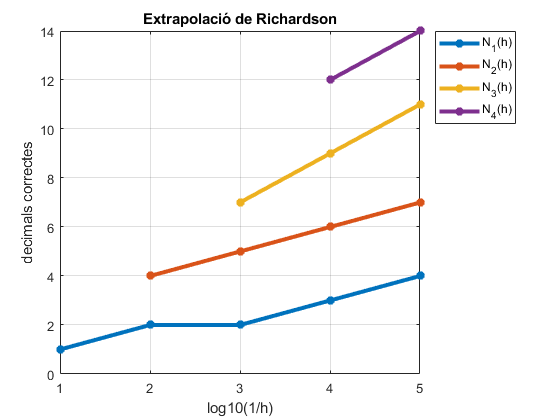

plot(1:5,-fix(log10(er1(1:5))),'-*',1:5,-fix(log10(er2(1:5))),'-*', ...
     1:5,-fix(log10(er3(1:5))),'-*',1:5,-fix(log10(er4(1:5))),'-*','LineWidth',3); grid;
xlabel('log10(1/h)'); ylabel('decimals correctes'); 
title('Extrapolació de Richardson');
legend('N_1(h)','N_2(h)','N_3(h)','N_4(h)','Location','bestoutside'), xticks([1:5])

% Mirant el gràfic de xifres decimals correctes, podem observar com
% aplicant una extrapolació a la aproximació del apartat 1, s'obté més
% decimals correctes (menys error). Per les 5 primeres k's, trobem una
% difèrencia de 2 decimals correctes a favor de N_2 en cada cas. I
% al aplicar una segona extrapolació obtenim més decimals correctes
% que N_2. I finalment al aplicar una última extrapolació obtenim 3 més
% decimals correctes que N_2.